## Motion Planning Assignment 2

Team Members:

- Siva Kishore

- Sahil Bobade

- Rushikesh Jadhav

- Saurabh Dandare

clear;
clc;
clf ;
robot = rigidBodyTree("DataFormat","row");
base = robot.Base;

Creating a series of linkages as `rigidBody` objects

rotatingBase = rigidBody("rotating_base");
arm1 = rigidBody("arm1");
arm2 = rigidBody("arm2");
arm3 = rigidBody("arm3");

Create collision objects for each rigid body.

collBase = collisionCylinder(0.01,0.15); % cylinder: radius,length
collBase.Pose = trvec2tform([0 0 0.15/2]);

coll1 = collisionCylinder(0.01,0.20);
coll1.Pose = trvec2tform([0 0 0.20/2]);

coll2 = collisionCylinder(0.01,0.20);
coll2.Pose = trvec2tform([0 0 0.20/2]);

coll3 = collisionCylinder(0.01,0.0001);
coll3.Pose = trvec2tform([0 0 0.0001/2]);


Add the collision bodies to the rigid body objects.

addCollision(rotatingBase,collBase)
addCollision(arm1,coll1)
addCollision(arm2,coll2)
addCollision(arm3,coll3)

Each rigid body is attached using a revolute joint.    

jntBase = rigidBodyJoint("base_joint","revolute");
jntBase.HomePosition = 0.0;
jnt1 = rigidBodyJoint("jnt1","revolute");
jnt1.HomePosition = 1.6;
jnt2 = rigidBodyJoint("jnt2","revolute");
jnt2.HomePosition = 0.8;
jnt3 = rigidBodyJoint("jnt3","revolute");
jnt3.HomePosition = 0;

jnt1.JointAxis = [1 0 0]; % x-axis
jnt2.JointAxis = [1 0 0];
jnt3.JointAxis = [1 0 0];


Set transformations of the joint attachment between bodies.

setFixedTransform(jnt1,trvec2tform([0 0 0.15]))
setFixedTransform(jnt2,trvec2tform([0 0 0.20]))
setFixedTransform(jnt3,trvec2tform([0 0 0.20]))

Create an object array for both the bodies and joints, including the original base. 

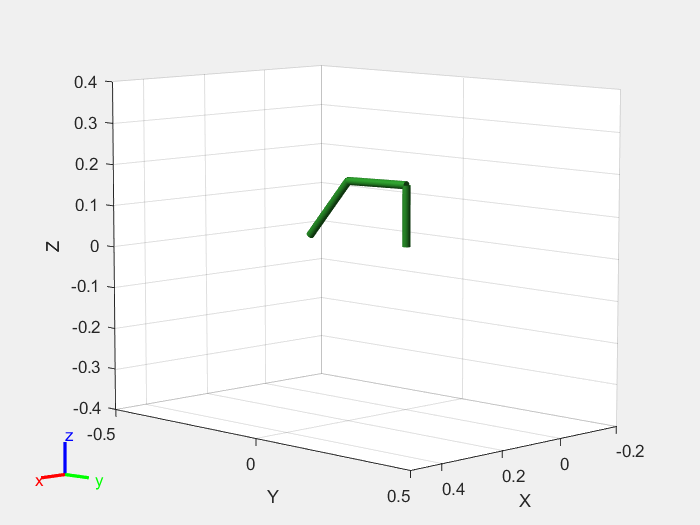

bodies = {base,rotatingBase,arm1,arm2, arm3}; 
joints = {[],jntBase,jnt1,jnt2, jnt3};

f_task = figure("Name","Assemble Robot","Visible","on");

for i = 2:length(bodies) % Skip base. Iterate through adding bodies and joints.
            bodies{i}.Joint = joints{i};
            addBody(robot,bodies{i},bodies{i-1}.Name)
            show(robot,"Collisions","on","Frames","off");
            xlim([-0.2 0.5]);
            ylim([-0.5 0.5]);
            zlim([-0.4 0.4]);
            drawnow;
end

Call the `showdetails` function to view a list of the final tree information. Ensure the parent-child relationship and joint types are correct.

%showdetails(robot)

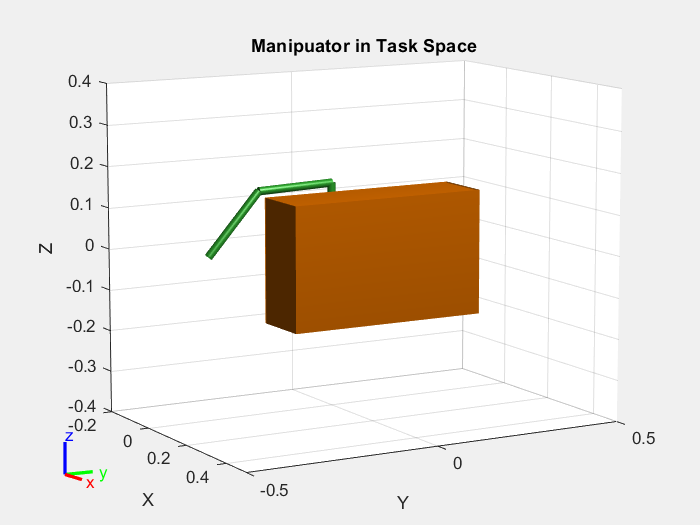

%Add an obstacle

config = homeConfiguration(robot);
figure(f_task)
pause(1)
show(robot,config, "Collisions","on","Frames","off");
title('Manipuator in Task Space')

hold on
ss = manipulatorStateSpace(robot);
sv = manipulatorCollisionBodyValidator(ss,SkippedSelfCollisions="parent");

sv.ValidationDistance = 0.05;
sv.IgnoreSelfCollision = true;

%obstacle
box = collisionBox(0.15,0.5,0.3); % XYZ Lengths
box.Pose = trvec2tform([0.2 0.0 0.0]); % XYZ Position
env = {box};
sv.Environment = env;

for i = 1:length(env)
    show(env{i})
    xlim([-0.2 0.5]);
    ylim([-0.5 0.5]);
    zlim([-0.4 0.4]);
end
view(60,10)


% finding collisions in C-space
gridInput= [];
t1_obs =[];
t2_obs =[];
t3_obs =[];
index =0;

d_theta =0.1;
pi1 =3.1;
n = (pi1/d_theta +1)^3;
i =0;
pause(1)
f = waitbar(0, 'Starting');
f.Name = 'Collecting obstacle data in C-space';


for theta1 = 0: d_theta: pi1
    for theta2 = 0: d_theta: pi1
        for theta3 = 0: d_theta: pi1

            temp_state = [theta1 theta2 theta3];
            validState = isStateValid(sv,[temp_state 0]);
            
            if validState % If state is valid, check motion between states.
               temp_config = [temp_state 0];  %no collision
            else
               temp_config = [temp_state 1];  % collision               
               t1_obs=[t1_obs theta1];
               t2_obs=[t2_obs theta2];
               t3_obs=[t3_obs theta3];
            end
            gridInput =[gridInput;
                        temp_config];
            waitbar(i/n, f, sprintf('Progress: %d %%', floor(i/n*100)));
            i = i+1;
             

        end    
    end
end
close(f)



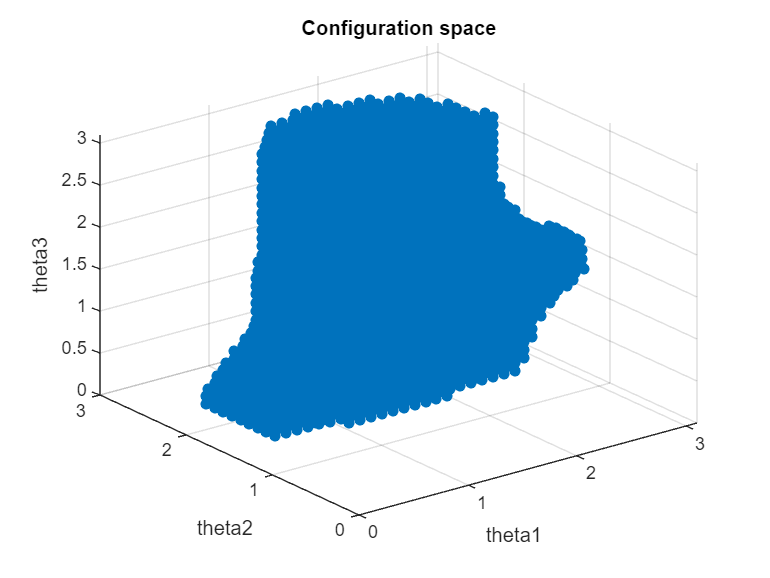

%plot obstacle in configuration space
f_obstacle = figure;
scatter3(t1_obs, t2_obs,t3_obs ,"filled");
title('Configuration space')
xlabel('theta1')
ylabel('theta2')
zlabel('theta3')
xlim([0 3.1])

% Get path by using A*

l1= length(t1_obs);
l2= length(t2_obs);
l3= length(t2_obs);
gridSize = [l1, l2, l3];
startPos = [0.0,  1.6, 00.8];
goalPos = [3.1  1.6 0.8];

path = astar_3d(startPos, goalPos, gridInput); 


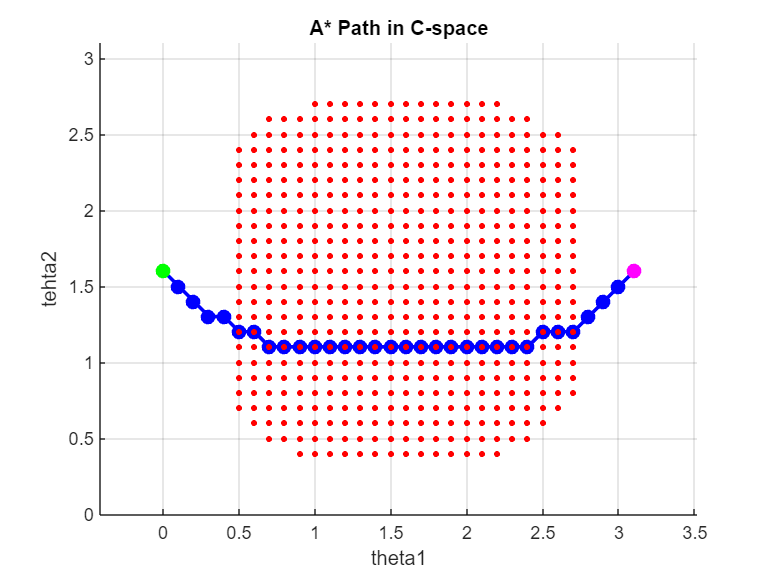

%visualising the path generated by A* in c-space 
visualize_path_and_grid(path, gridInput, 0.1)

% animating Task and Configuration Space

% Screen dimensions
screenSize = get(0, 'ScreenSize');  % Gets the size of your display
figWidth = 560;  % Standard MATLAB figure width
figHeight = 420;  % Standard MATLAB figure height
space = 25;  % Space between figures
verticalOffset = 50;  % Lower the window position by 50 pixels
bottom = screenSize(4)/2 - verticalOffset;  % Lower the vertical position

% Calculate positions
left1 = (screenSize(3) - 2 * figWidth - space) / 2;  % Horizontally center figures
left2 = left1 + figWidth + space;

%for configuration Space figure
obstacles = gridInput(gridInput(:,4) == 1, 1:3);
f1 = figure('Name', 'Configuration Space','visible', 'on');
set(f1, 'Position', [left1 bottom figWidth figHeight]);  % Position figure 1


% Initial plot setup for Figure 1 (configuration Space)
figure(f1);
plot3(obstacles(:,1), obstacles(:,2), obstacles(:,3), 'r.', 'MarkerSize', 10);
xlim([0 3.1]);
hold on; % Hold on to add more plots in the same figure
xlabel('theta1'); ylabel('theta2'); zlabel('theta3');
title('Configuration Space')
axis manual;
view(3);

% Initial plot setup for Figure 2 (Task Space)
figure(f_task);
set(f_task, 'Position', [left2 bottom figWidth figHeight]);  % Position figure 2
title('Task Space')
eePose = nan(3,size(path,1));
xlabel('X'); ylabel('Y'); zlabel('Z');
axis manual;
view(3);

% Animation loop
for i = 1:size(path, 1)
    % Update Figure 1
    figure(f1);
    plot3(path(1:i, 1), path(1:i, 2), path(1:i, 3), 'bo-', ...
          'MarkerSize', 8, 'MarkerFaceColor', 'b');

    % Update Figure 2
    figure(f_task);
    show(robot, [path(i,:) 0],"Collisions","on","Frames","off",PreservePlot=false);
    eePos(i,:) = tform2trvec(getTransform(robot,[path(i,:) 0],"arm3")); % XYZ translation vector
    
    plot3(eePos(:,1),eePos(:,2),eePos(:,3),"-b",LineWidth=2)

    
    % Optional: pause each frame to slow down the animation
    pause(0.5);
end





functions

function visualize_path_and_grid(path, gridInput, resolution)
    % Define the grid size from resolution and maximum grid values
    gridSize = max(gridInput(:, 1:3)) / resolution + 1;

    % Initialize the figure
    figure;
    hold on;
    axis equal;
    grid on;
    xlabel('theta1');
    ylabel('tehta2');
    zlabel('theta3');
    title('A* Path in C-space')

    % Plot the obstacles as points
    obstacles = gridInput(gridInput(:,4) == 1, 1:3);  % Assuming 4th column is occupancy status with 1 being an obstacle
    plot3(obstacles(:,1), obstacles(:,2), obstacles(:,3), 'r.', 'MarkerSize', 10);

    % Plot the path
    if ~isempty(path)
        plot3(path(:,1), path(:,2), path(:,3), 'b-o', 'LineWidth', 2, 'MarkerFaceColor', 'b');
    end
    plot3(path(1,1), path(1,2), path(1,3), 'g-o', 'LineWidth', 2, 'MarkerFaceColor', 'g');
    plot3(path(end,1), path(end,2), path(1,3), 'm-o', 'LineWidth', 2, 'MarkerFaceColor', 'm');
    hold off;
end


function path = astar_3d(startPos, goalPos, grid)
    resolution = 0.1;
    gridSize = 32; % Since maxX, maxY, maxZ = 3.1, and step = 0.1

    % Create the occupancy grid
    occupancyGrid = zeros(gridSize, gridSize, gridSize);
    for i = 1:size(grid, 1)
        x = floor(1+grid(i,1)*10);
        y = floor(1+grid(i,2)*10);
        z = floor(1+grid(i,3)*10);
        val = grid(i, 4);
        occupancyGrid(x, y, z) = val;        
    end

    % Initialize lists
    openList = containers.Map('KeyType', 'char', 'ValueType', 'any');
    closedList = containers.Map('KeyType', 'char', 'ValueType', 'any');

    % Heuristic function: Euclidean distance
    heuristic = @(pos1, pos2) sqrt(sum(((pos1 - pos2) * resolution).^2));

    % Start and goal nodes index conversion
    startPosIdx = 1+ startPos*10;
    goalPosIdx = 1+ goalPos*10;

    % Define the start and goal nodes
    startNode = struct('Position', startPosIdx, 'Parent', [], 'G', 0, 'H', heuristic(startPosIdx, goalPosIdx), 'F', heuristic(startPosIdx, goalPosIdx));
    goalNode = struct('Position', goalPosIdx);

    % Add start node to open list
    openList(pos2key(startNode.Position)) = startNode;

    % A* algorithm main loop
    while ~isempty(openList)
        currentNode = extractMinF(openList);
        if all(currentNode.Position == goalNode.Position)
            path = (reconstructPath(currentNode) -1) * resolution;
            return;
        end

        % Remove the current node from the open list and add to the closed list
        openList.remove(pos2key(currentNode.Position));
        closedList(pos2key(currentNode.Position)) = currentNode;

        % Process each potential neighbor
        for dx = -1:1
            for dy = -1:1
                for dz = -1:1
                    if dx == 0 && dy == 0 && dz == 0
                        continue;
                    end
                    neighborPos = currentNode.Position + [dx, dy, dz];
                    if isInsideGrid(neighborPos, gridSize) && occupancyGrid(neighborPos(1), neighborPos(2), neighborPos(3)) == 0
                        if ~isKey(closedList, pos2key(neighborPos))
                            tentativeG = currentNode.G + heuristic(currentNode.Position, neighborPos);
                            if ~isKey(openList, pos2key(neighborPos)) || tentativeG < openList(pos2key(neighborPos)).G
                                neighborNode = struct('Position', neighborPos, 'Parent', currentNode, 'G', tentativeG, 'H', heuristic(neighborPos, goalPosIdx), 'F', tentativeG + heuristic(neighborPos, goalPosIdx));
                                openList(pos2key(neighborPos)) = neighborNode;
                            end
                        end
                    end
                end
            end
        end
    end

    % If no path is found
    path = [];
end


% Helper functions
function key = pos2key(position)
    key = sprintf('%d-%d-%d', position(1), position(2), position(3));
end

function node = extractMinF(openList)
    minF = inf;
    minNode = []; 
    keys = openList.keys;
    for i = 1:length(keys)
        currentNode = openList(keys{i});
        if currentNode.F < minF
            minF = currentNode.F;
            minNode = currentNode;
        end
    end
    node = minNode;
end


function result = isInsideGrid(pos, gridSize)
    result = all(pos > 0 & pos <= gridSize);
end

function path = reconstructPath(node)
    path = [];
    while ~isempty(node)
        path = [node.Position; path];
        node = node.Parent;
    end
end

